% Main File to generate Baseline Model Figures 10-11
close all; clear; clc

load ICs_baseline
load baseline_parameter_inputs

% ========================================================================
%  START: EXPERIMENTAL CONFIGURATION BLOCK
% ========================================================================

% --- 1. SELECT WHICH MODEL TO RUN ---
% 0 = Baseline (Isogenic Control)
% 1 = Model 1 (IKr Defect Only)
% 2 = Model 2 (IKr + INa,L)
% 3 = Model 3 (IKr + ICa,L)
% 4 = Model 4 (All Three Defects)
model_to_run = 3; % <--- CHANGE THIS NUMBER TO SELECT YOUR EXPERIMENT

% --- 2. Define Parameter Indices ---
g_Kr_index = 2;   % Conductance of IKr
g_Na_index = 7;  % Conductance of INa 
p_CaL_index = 5; % Permeability of ICaL
g_K1_index = 1;   % Conductance of IK1 (Added for stabilization)
% --- These are NOT used for persistent currents ---

% NEW index for the parameter we created in ipsc_function.m
C_persist_CaL_index = 86; % New persistent ICaL parameter (baseline = 0.0126 or 1.26%)
C_persist_NaL_index = 87; % Persistent INaL parameter (baseline = 0.0026 or 0.26%)

% --- 3. Apply Modifications Based on Selection ---
modified_params = baseline_parameter_inputs; % Start with the baseline

% This is the master "on/off" switch for pacing.
modified_params(83) = 1; % Off = 0 | ON = 1

% This is the master "on/off" switch for square pulse voltage patch-clamp.
modified_params(85) = 0; % Off = 0 | ON = 1

% IMPORTANT: Get the baseline persistent current value
% This is what we will scale by 2.29-fold OR 2.31-fold
baseline_C_persist_CaL = modified_params(C_persist_CaL_index);
baseline_C_persist_NaL = modified_params(C_persist_NaL_index);

    modified_params(g_K1_index) = modified_params(g_K1_index) * 5; % Kernik-Clancy Mature iPSC-CM
    modified_params(g_Na_index) = modified_params(g_Na_index) * 1.45; % Kernik-Clancy Mature iPSC-CM

if model_to_run == 1
    plot_title = 'Model 1: IKr Defect Only';
    % Apply 72.5% IKr reduction
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);


elseif model_to_run == 2
    plot_title = 'Model 2: IKr + INa,L';
    % Apply IKr reduction
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);

    % --- CORRECTED INa,L LOGIC ---
    % Apply 2.31-fold INa,L increase
    modified_params(C_persist_NaL_index) = baseline_C_persist_NaL * 2.31;
    % --- END CORRECTION ---

elseif model_to_run == 3
    plot_title = 'Model 3: IKr + ICa,L';
    % Apply IKr reduction
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);

    % --- CORRECTED persistent non-inactivating ICa,L LOGIC ---
    % Apply 2.29-fold ICa,L increase (from your previous query)
    modified_params(C_persist_CaL_index) = baseline_C_persist_CaL * 2.29;
    % --- END CORRECTION ---
    
elseif model_to_run == 4
    plot_title = 'Model 4: All Three Defects';
    % Apply all three modifications
    modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    modified_params(C_persist_NaL_index) = baseline_C_persist_NaL * 2.31;
    modified_params(C_persist_CaL_index) = baseline_C_persist_CaL * 2.29;


else % Default to baseline if model_to_run is 0 or any other number
    plot_title = 'Baseline Model (Isogenic Control)';
end

% Overwrite the original variable with our modified one for the simulation
baseline_parameter_inputs = modified_params;
% ========================================================================
%  END: CONFIGURATION BLOCK
% ========================================================================

## iPSC_function

options = odeset('MaxStep',1,'InitialStep',2e-2);
run_time=11e3;
[Time, values] = ode15s(@ipsc_function,[0, run_time],Y_init, options, baseline_parameter_inputs);
Cai=values(:,3);
Vm=values(:,1);

## Calculate select current traces:

INaCa = zeros(size(Time));
IpCa = zeros(size(Time));
Iup = zeros(size(Time));
Istim = zeros(size(Time)); % <-- 1. ADD THIS LINE%%%%%%%%%%%%%%%%%%%%%%

for i= 1:size(values,1)
    [~, update_step_i] =  ipsc_function(Time(i), values(i,:),  baseline_parameter_inputs);
    INaCa(i) = update_step_i(8);
    IpCa(i) = update_step_i(9);
    Iup(i) = update_step_i(14);
    Istim(i) = update_step_i(16); % <-- 2. ADD THIS LINE %%%%%%%%%%%%%%%%
end

## Figure 10A & 10C: Calcium Flux analysis and Calcium Transient Trace

%ca_analysis_v6( Time, Iup, INaCa, IpCa, Cai, plot_title )

## Figure 11A: action potential trace for baseline model

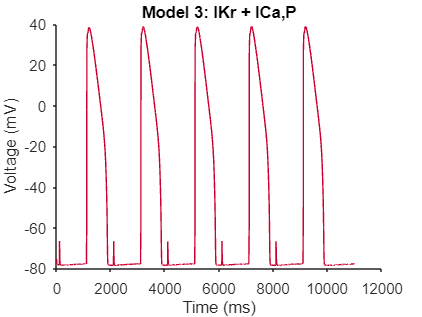

figure,set(gcf,'color','w')
plot(Time, Vm,'Color', [.8 0 .18]);
set(gca,'box','off','tickdir','out')
ylabel('Voltage (mV)');
xlabel('Time (ms)')
title(plot_title)


% ... after the Vm plot ...

Stimulus Verify Pacing

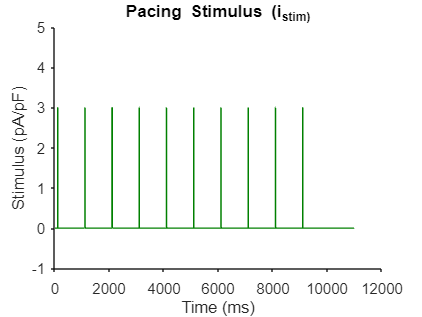

% --- Plot the Stimulus to Verify Pacing ---
figure,set(gcf,'color','w')
plot(Time, Istim,'Color', [0 .5 0]);
set(gca,'box','off','tickdir','out')
ylabel('Stimulus (pA/pF)');
xlabel('Time (ms)')
title('Pacing Stimulus (i_stim)')
ylim([-1 5]); % Zoom in to see the pulses

## Figure 10A & 10C: Calcium Flux analysis and Calcium Transient Trace

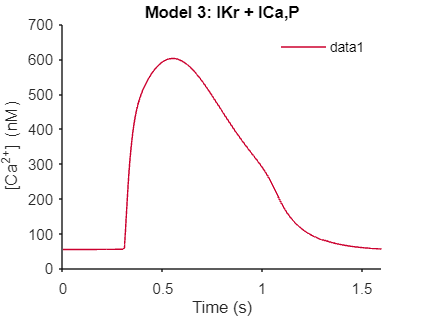

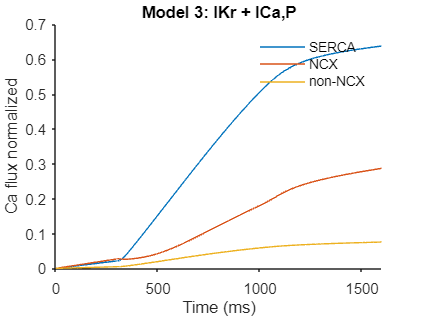

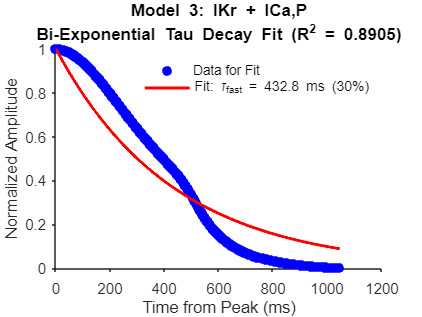

[ca_results, validation_data] = ca_analysis_v6( Time, Iup, INaCa, IpCa, Cai, plot_title );

## ========================================================================

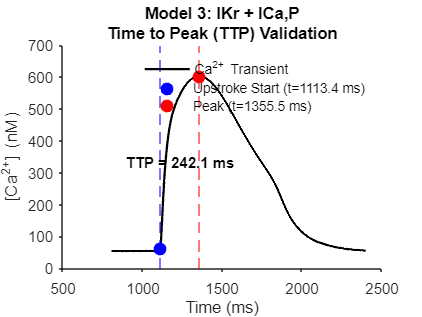

%% =======================================================================
%  START: TTP VALIDATION PLOT
%  =======================================================================
figure, set(gcf,'color','w');
hold on;

% --- Get data from the validation struct ---
% Note: ca_beat is in mM, so multiply by 1e6 for nM
time_vec_ms = validation_data.time_beat;
ca_vec_nM = validation_data.ca_beat * 1e6;

% Get time and Ca values for markers
upstroke_idx = validation_data.upstroke_idx;
peak_idx = validation_data.peak_idx;

time_upstroke = time_vec_ms(upstroke_idx);
ca_upstroke = ca_vec_nM(upstroke_idx);
time_peak = time_vec_ms(peak_idx);
ca_peak = ca_vec_nM(peak_idx);

% --- Plot the full transient ---
plot(time_vec_ms, ca_vec_nM, 'k-', 'LineWidth', 1.5, 'DisplayName', 'Ca^{2+} Transient');

% --- Add Markers for TTP ---
% Mark the start of the upstroke (max dCa/dt)
plot(time_upstroke, ca_upstroke, 'bo', ...
    'MarkerFaceColor', 'b', ...
    'MarkerSize', 8, ...
    'DisplayName', sprintf('Upstroke Start (t=%.1f ms)', time_upstroke));

% Mark the peak
plot(time_peak, ca_peak, 'ro', ...
    'MarkerFaceColor', 'r', ...
    'MarkerSize', 8, ...
    'DisplayName', sprintf('Peak (t=%.1f ms)', time_peak));

% --- Add helper lines and text ---
% Add vertical lines
xline(time_upstroke, 'b--', 'HandleVisibility', 'off');
xline(time_peak, 'r--', 'HandleVisibility', 'off');

% Add TTP arrow/text
% (This code draws a horizontal arrow between the two points)
text_y_pos = ca_upstroke + (ca_peak - ca_upstroke) * 0.5;
text_x_pos = time_upstroke + (time_peak - time_upstroke) * 0.5;

text(text_x_pos, text_y_pos, sprintf('TTP = %.1f ms', ca_results.ttp_ms), ...
    'Color', 'k', 'FontSize', 10, 'HorizontalAlignment', 'center', 'FontWeight', 'bold');

hold off;

% --- Format Plot ---
title({plot_title; 'Time to Peak (TTP) Validation'});
xlabel('Time (ms)');
ylabel('[Ca^{2+}] (nM)');
legend('show', 'Location', 'northeast');
legend boxoff;
set(gca, 'box', 'off', 'tickdir', 'out');

fprintf('\n\n--- DATA TABLES FOR: %s ---\n', plot_title);



--- DATA TABLES FOR: Model 3: IKr + ICa,P ---



% --- Display Calcium and Flux Tables (from ca_analysis_v6) ---
fprintf('\n## Table 1: Calcium Transient Morphology ##\n');


## Table 1: Calcium Transient Morphology ##


fprintf('%-30s | %-10.2f\n', 'Peak [Ca²⁺] (nM)', ca_results.peak_ca_nM);

Peak [Ca²⁺] (nM)               | 602.01    


fprintf('%-30s | %-10.2f\n', 'Diastolic [Ca²⁺] (nM)', ca_results.diastolic_ca_nM);

Diastolic [Ca²⁺] (nM)          | 54.00     


fprintf('%-30s | %-10.2f\n', 'Time to Peak (ms)', ca_results.ttp_ms);

Time to Peak (ms)              | 242.10    


fprintf('%-30s | %-10.2f\n', 'Tau Decay Fast (ms)', ca_results.tau_fast_ms);

Tau Decay Fast (ms)            | 432.77    


fprintf('%-30s | %-10.2f\n', 'Tau Decay Slow (ms)', ca_results.tau_slow_ms);

Tau Decay Slow (ms)            | 432.77    


fprintf('%-30s | %-10.2f\n', 'R^2 Tau Decay', ca_results.tau_decay_r_squared);

R^2 Tau Decay                  | 0.89      



fprintf('\n## Table 2: %% Contribution of Calcium Flux ##\n');


## Table 2: % Contribution of Calcium Flux ##


fprintf('%-30s | %-10.1f%%\n', 'SERCA', ca_results.pct_serca);

SERCA                          | 63.8      %


fprintf('%-30s | %-10.1f%%\n', 'NCX', ca_results.pct_ncx);

NCX                            | 28.7      %


fprintf('%-30s | %-10.1f%%\n', 'Non-NCX (I_pCa)', ca_results.pct_ipca);

Non-NCX (I_pCa)                | 7.6       %


## Calculate and Display AP Morphology Table

    % --- C. NEW: Match variable names ---
    % Assign the loaded data to the variable names our functions expect.
    voltage = Vm;   % Assign data from 'Vm' to 'voltage'
    time = Time;    % Assign data from 'Time' to 'time'
    clear Vm Time;  % Good practice to clear the original variables
    
    % --- D. Run the analysis by CALLING the functions ---
    disp('Starting analysis...');

Starting analysis...


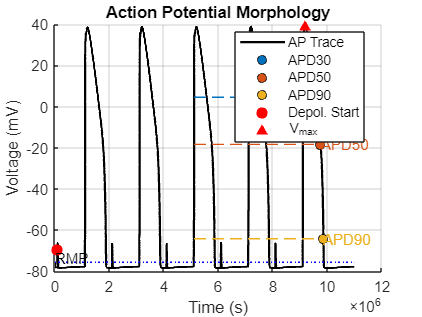

    
    results = CalculateAPMorphology(time, voltage); % 1. Perform calculations
    DisplayAPMorphology(time, voltage, results);     % 2. Create the plot

    DisplayAPMorphologyTable(results);               % 3. Show the results table


--- Action Potential Morphology ---
Parameter         Value Units   
-----------------------------------
Resting Membrane Potential     -75.73 mV      
Amplitude        114.65 mV      
Vmax              38.93 mV      
dV/dt max        124.02 V/s     
APD30           4466.54 ms      
APD50           4652.72 ms      
APD90           4753.75 ms      



    
    disp('Analysis complete.');

Analysis complete.


    function results = CalculateAPMorphology(time, voltage)
    % Calculates action potential morphology parameters using linear interpolation.
    % CORRECTED VERSION: Assumes the 'time' vector is in microseconds (µs).

    % --- NEW: Define a search window for the AP peak (in microseconds) ---
    % 500 ms is a safe window, which equals 500,000 µs.
    peak_search_window_us = 500000; 

    % --- Find Max Upstroke Velocity (dV/dt) to anchor the analysis ---
    % dVdt will be in mV/µs
    dVdt = diff(voltage) ./ diff(time);
    [dVdt_max, idx_dVdt_max] = max(dVdt);
    t_depol = time(idx_dVdt_max); % This is time of dVdt_max (reference for APD)

    % --- MODIFIED: Search for the AP peak ONLY after the upstroke ---
    % 1. Determine the average time step (sampling interval) in µs
    sampling_interval_us = mean(diff(time));
    
    % 2. Calculate the window size in array indices
    window_indices = round(peak_search_window_us / sampling_interval_us);
    search_start_idx = idx_dVdt_max;
    search_end_idx = min(search_start_idx + window_indices, length(voltage));
    
    % 3. Find the peak voltage and its index within the defined window
    [V_max, local_idx_max] = max(voltage(search_start_idx:search_end_idx));
    
    % 4. Convert the local index back to the global index of the original trace
    idx_max = search_start_idx + local_idx_max - 1;
    t_peak = time(idx_max);

    % --- Standard Calculations ---
    RMP = mean(voltage(1:10)); 
    APA = V_max - RMP;

    % ***************************************************************
    % --- NEW: Find the true AP Start time (t_AP_start) using RMP + 1mV ---
    V_threshold = RMP + 6; % 6mV above RMP 

    % Search before the max upstroke point
    depol_phase_voltage = voltage(1:idx_dVdt_max);
    depol_phase_time = time(1:idx_dVdt_max);

    % Find the first index where voltage crosses the threshold
    idx1_start_cross = find(depol_phase_voltage > V_threshold, 1, 'first');

    if ~isempty(idx1_start_cross) && idx1_start_cross > 1
        % Interpolate the exact time of the threshold crossing
        t1 = depol_phase_time(idx1_start_cross - 1);
        v1 = depol_phase_voltage(idx1_start_cross - 1);
        t2 = depol_phase_time(idx1_start_cross);
        v2 = depol_phase_voltage(idx1_start_cross);
        t_AP_start = interpolate_time(t1, v1, t2, v2, V_threshold);
        V_AP_start = V_threshold;
    else
        % Fallback: Use the first data point if crossing is not found
        t_AP_start = time(1);
        V_AP_start = RMP;
    end
    % ***************************************************************

    % --- APD Calculations ---
    repol_phase_time = time(idx_max:end);
    repol_phase_voltage = voltage(idx_max:end);
    
    apd_levels = [30, 50, 90]; 
    
    results.t_rep = zeros(length(apd_levels), 1);
    results.v_rep = zeros(length(apd_levels), 1);
    
    for i = 1:length(apd_levels)
        level = apd_levels(i);
        V_rep_target = V_max - (level/100) * APA;
        idx2_repol = find(repol_phase_voltage < V_rep_target, 1, 'first');
        
        if ~isempty(idx2_repol) && idx2_repol > 1
            t1 = repol_phase_time(idx2_repol - 1);
            v1 = repol_phase_voltage(idx2_repol - 1);
            t2 = repol_phase_time(idx2_repol);
            v2 = repol_phase_voltage(idx2_repol);
            t_interpolated = interpolate_time(t1, v1, t2, v2, V_rep_target);
            
            % --- Store results with CORRECT unit conversion ---
            % Duration (t_interpolated - t_depol) 
            results.(['APD' num2str(level)]) = (t_interpolated - t_depol); % APD in ms
            results.t_rep(i) = t_interpolated;
            results.v_rep(i) = V_rep_target;
        else
            results.(['APD' num2str(level)]) = NaN;
            results.t_rep(i) = NaN;
            results.v_rep(i) = NaN;
        end
    end
    
    % --- Store other results with CORRECT unit conversion ---
    results.RMP = RMP;
    results.APA = APA;
    results.V_max = V_max;
    results.t_peak = t_peak;
    results.t_depol = t_depol; % Time of dVdt_max (used as APD reference)
    results.t_AP_start = t_AP_start; % Time of RMP + 1mV (used for plotting/onset)
    results.V_AP_start = V_AP_start; % The RMP + 1mV threshold voltage
    % dVdt_max is in mV/s. (1000 mV/s = 1 V/s)    % dVdt_max is in mV/µs. (1 mV/µs = 1000 V/s).
    results.dVdt_max = dVdt_max * 1000; % dV/dt in V/s

end

% --- Helper function for linear interpolation (unchanged) ---
function t_interp = interpolate_time(t1, v1, t2, v2, v_target)
    t_interp = t1 + (v_target - v1) * (t2 - t1) / (v2 - v1);
end

function DisplayAPMorphology(time, voltage, results)
    % Displays the action potential and overlays the calculated morphology parameters.
    
    figure;
    hold on;
    
    % Plot the main AP trace
    plot(time * 1000, voltage, 'k-', 'LineWidth', 1.5);
    title('Action Potential Morphology');
    xlabel('Time (s)');
    ylabel('Voltage (mV)');
    grid on;
    
    % --- Plot Interpolated APD Markers and Lines ---
    apd_levels = [30, 50, 90];
    colors = lines(length(apd_levels));
    
    for i = 1:length(apd_levels)
        t_rep_val = results.t_rep(i);
        v_rep_val = results.v_rep(i);
        
        if ~isnan(t_rep_val)
            % Plot a marker at the exact interpolated point
            plot(t_rep_val * 1000, v_rep_val, 'o', 'MarkerFaceColor', colors(i,:), 'MarkerEdgeColor', 'k');
            
            % --- CHANGED: Plot horizontal line from t_depol to t_rep ---
            line([results.t_depol, t_rep_val] * 1000, [v_rep_val, v_rep_val], ...
                 'Color', colors(i,:), 'LineStyle', '--');
            
            % Add a text label
            text(t_rep_val * 1000 + 5, v_rep_val, ['APD' num2str(apd_levels(i))], 'Color', colors(i,:));
        end
    end
    
    % --- Plot other features ---

    % *** MODIFIED CODE for Depolarization Start Time (RMP + 1mV) ***
    t_plot = results.t_AP_start;
    V_plot = results.V_AP_start;
    
    % 2. Mark the AP start time (t_AP_start) with a red dot
    plot(t_plot * 1000, V_plot, 'ro', 'MarkerSize', 7, 'MarkerFaceColor', 'r');
    % **********************************************

    % Mark the peak voltage
    plot(results.t_peak * 1000, results.V_max, 'r^', 'MarkerFaceColor', 'r');
    
    % Mark the RMP
    line([time(1), time(end)]*1000, [results.RMP, results.RMP], 'Color', 'b', 'LineStyle', ':');
    text(time(5)*1000, results.RMP + 2, 'RMP');
    
    hold off;
    legend('AP Trace', 'APD30','', 'APD50','', 'APD90','', 'Depol. Start', 'V_{max}', 'Location', 'best');
end



function DisplayAPMorphologyTable(results)
    % Displays the calculated AP morphology parameters in a formatted table.
    
    % Create a header for the table
    fprintf('\n--- Action Potential Morphology ---\n');
    fprintf('===================================\n');
    fprintf('%-12s %10s %-8s\n', 'Parameter', 'Value', 'Units');
    fprintf('-----------------------------------\n');
    
    % Populate the table with data from the results struct
    fprintf('%-12s %10.2f %-8s\n', 'Resting Membrane Potential', results.RMP, 'mV');
    fprintf('%-12s %10.2f %-8s\n', 'Amplitude', results.APA, 'mV');
    fprintf('%-12s %10.2f %-8s\n', 'Vmax', results.V_max, 'mV');
    fprintf('%-12s %10.2f %-8s\n', 'dV/dt max', results.dVdt_max / 1000, 'V/s');
    fprintf('%-12s %10.2f %-8s\n', 'APD30', results.APD30, 'ms');
    fprintf('%-12s %10.2f %-8s\n', 'APD50', results.APD50, 'ms');
    fprintf('%-12s %10.2f %-8s\n', 'APD90', results.APD90, 'ms');
    
    fprintf('===================================\n\n');
end
